# **Arm Circle Analysis**

## **Data Analysis**

### **Load, Trim, and Filter Data**

% Load and Parse Data
[ArmMotionData]=ParseMatlabApp('Data/arm_circle_ten_seconds.mat');

% Trim data to isolate exercise
time = ArmMotionData.t_Accel(5:105);
arm_acceleration = ArmMotionData.Accel(5:105, :);

% Apply Moving Average Filter
x = arm_acceleration(:,1);
y = arm_acceleration(:,2);
z = arm_acceleration(:,3);
arm_accelerationx = [x(1) + x(2); x(1:end-2) + x(2:end-1) + x(3:end); x(end-1) + x(end)]/3;
arm_accelerationy = [y(1) + y(2); y(1:end-2) + y(2:end-1) + y(3:end); y(end-1) + y(end)]/3;
arm_accelerationz = [z(1) + z(2); z(1:end-2) + z(2:end-1) + z(3:end); z(end-1) + z(end)]/3;
arm_acceleration_filtered = [arm_accelerationx arm_accelerationy arm_accelerationz];

### Plot Filtered Time Domain

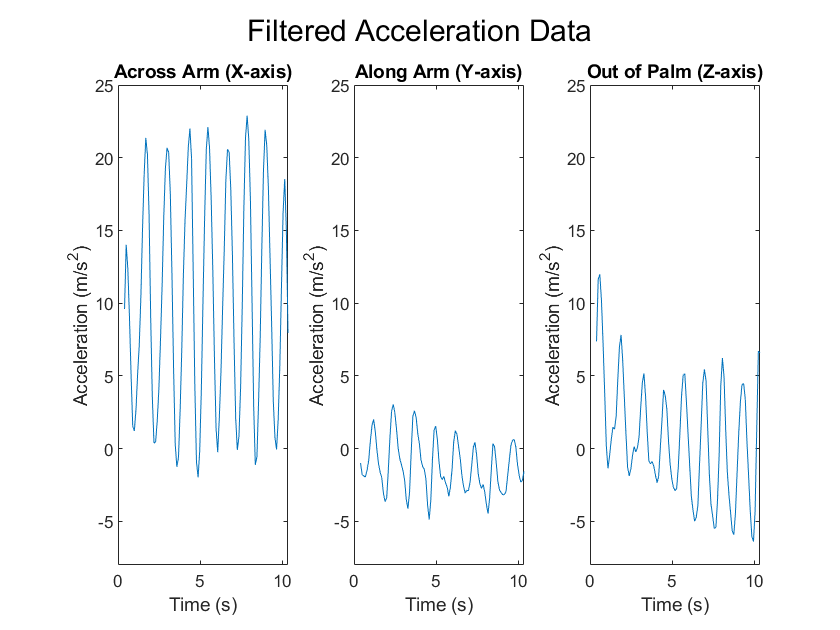

% Plot Time Domain
% Plot Raw Data
% makeAccelerometerPlots([time,arm_acceleration], {'Across Arm Raw', 'Along Arm Raw', 'In direction Coming out of Palm'})

% Plot Filtered Data
% Subplot 1
clf;
p1 = subplot(131);
plot(time, arm_accelerationx)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Across Arm (X-axis)')

% Subplot 2
p2 = subplot(132);
plot(time, arm_accelerationy)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Along Arm (Y-axis)')

% Subplot 3
p3 = subplot(133);
plot(time, arm_accelerationz)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Out of Palm (Z-axis)')

sgtitle('Filtered Acceleration Data') 
linkaxes([p1, p2, p3]);

### Calculate & Plot Fourier Transformations

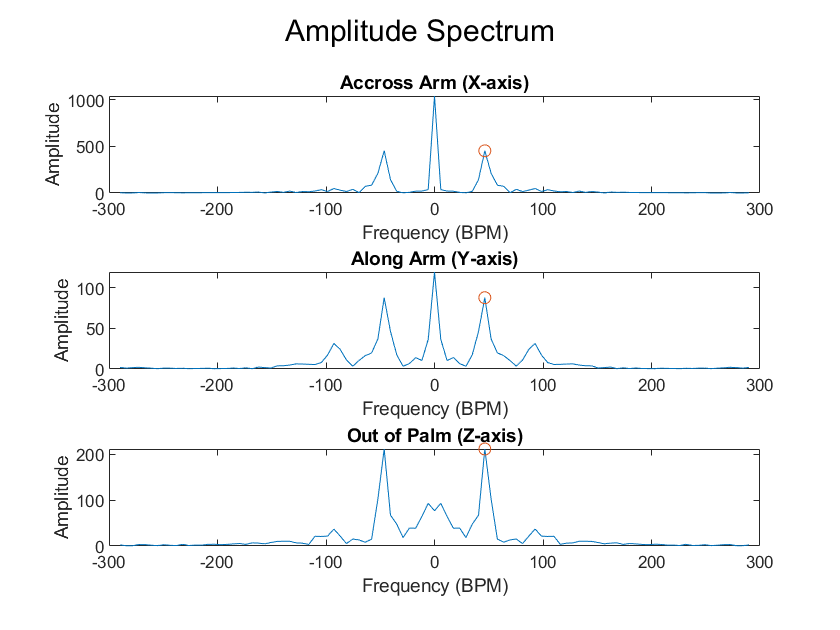

% Calculate Fourier Transform Frequencies
N = length(time);
time_elapsed = time(end);
Fs = length(time)/time_elapsed;
frequencies_shifted = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
%^^ based on lowest and highest frequencies we found above
%^^ mod is to account for if its even or odd
fourier_frequenciesx = fftshift(fft(arm_acceleration_filtered(:,1)));
fourier_frequenciesy = fftshift(fft(arm_acceleration_filtered(:,2)));
fourier_frequenciesz = fftshift(fft(arm_acceleration_filtered(:,3)));

% Plot Fourier Transformations
% converts from rad/s to bpm
convert_to_bpm = 1/0.10471975499997;

% Subplot 1
clf;
subplot(3, 1, 1);
% find two highest peaks
[pksx,locsx] = findpeaks(abs(fourier_frequenciesx), frequencies_shifted*convert_to_bpm, 'SortStr', 'descend', 'Npeaks', 2);
% find highest peak excluding 0 
[max_frequencyx, max_amplitudex] = find_largest_frequency(locsx, pksx);
% plot ft and peak excluding 0 
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesx),max_frequencyx,max_amplitudex, 'o');
xlabel('Frequency (BPM)')
ylabel('Amplitude')
title("Accross Arm (X-axis)")

% Subplot 2
subplot(3, 1, 2);
% find two highest peaks
[pksy,locsy] = findpeaks(abs(fourier_frequenciesy), frequencies_shifted*convert_to_bpm, 'SortStr', 'descend', 'Npeaks', 2);
% find highest peak excluding 0 
[max_frequencyy, max_amplitudey] = find_largest_frequency(locsy, pksy);
% plot ft and peak excluding 0 
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesy), max_frequencyy, max_amplitudey, 'o');
xlabel('Frequency (BPM)')
ylabel('Amplitude')
title("Along Arm (Y-axis)")

% Subplot 3
subplot(3, 1, 3);
% find two highest peaks
[pksz,locsz] = findpeaks(abs(fourier_frequenciesz), frequencies_shifted*convert_to_bpm, 'SortStr', 'descend', 'Npeaks', 2);
% find highest peak excluding 0
[max_frequencyz, max_amplitudez] = find_largest_frequency(locsz, pksz);
% plot ft and peak excluding 0 
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesz), max_frequencyz, max_amplitudez, 'o');
xlabel('Frequency (BPM)')
ylabel('Amplitude')
title('Out of Palm (Z-axis)')

sgtitle('Amplitude Spectrum') 

## Performance Feedback

### Tempo

% find tempo by averaging the frequency (in bpm) of the exercise in all
tempo_actual = (max_frequencyx + max_frequencyy + max_frequencyz)/3;
% get tempo feedback
tempo_feedback = tempo_analysis(50, tempo_actual)

tempo_feedback = "Your tempo is great."

### Shape

% find ratio of the x axis highest amplitude to the z axis highest
% amplitude
ratio_XtoZ = max_amplitudex/max_amplitudez;

% get feedback on the shape of the exercise
% threshold for the ratio to be considered too horizontal or too vertical
ratio_threshold = 3;
shape_feedback = shape_analysis(ratio_XtoZ, ratio_threshold)

shape_feedback = "Your circle shape is looking great!"